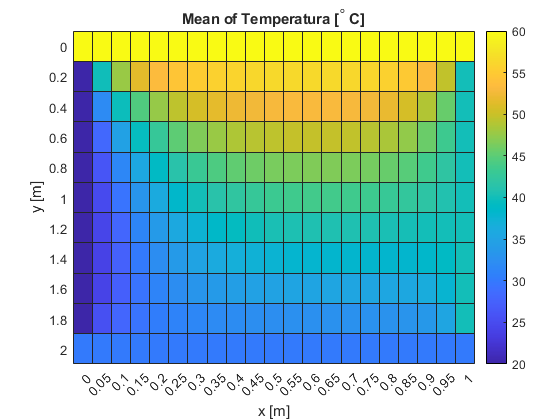

clear,clc,close all
L=1;
W=2;
f=@(x,y) sin(x)+cos(y);
dx=0.05;
dy=0.2;
x=0:dx:L;
y=0:dy:W;

iterations=0;
gradient=1;
convergence=0.01;

alpha=(sin(pi/(2*max(length(x)-1,length(y)-1))))^2;
k=1;
while (sqrt(2)-1)^(2*k)>=alpha;
    k=k+1;
end
for i=1:k
    r(i)=alpha^((1-2*i)/(2*k));
end

% przyblizenie poczatkowe
A=ones(length(y),length(x));
init=25;
A=A*init;
A(1:end,1)=20; % lewy
A(1:end,end)=40; % prawy
A(1,1:end)=60; % gora
A(end,1:end)=30; % dol
%macierze wynikowe
A12=zeros(length(y),length(x));
B=zeros(length(y),length(x));
tic
while gradient > convergence
    % A12
    mcoeff12=zeros((length(x)-2)*(length(y)-2));
    main=ones(1,(length(x)-2)*(length(y)-2))*(1+2*r(1));
    diag2=ones(1,(length(x)-2)*(length(y)-2)-1).*(-r(1));
    for z=length(x)-2:length(x)-2:length(diag2)
        diag2(z)=0;
    end
    mcoeff12=mcoeff12+diag(main)+diag(diag2,1)+diag(diag2,-1);
    A12(1:end,1)=A(1:end,1); % lewy
    A12(1:end,end)=A(1:end,end); % prawy
    A12(1,1:end)=A(1,1:end); % gora
    A12(end,1:end)=A(end,1:end); % dol
    o=1;
    for i=2:length(y)-1
        for j=2:length(x)-1
            BC12(o,1)=A(i,j)+r(1)*(A(i-1,j)+A(i+1,j)-2*A(i,j))-r(1)*dx*dy*f(x(j),y(i));
            if j==2
                BC12(o,1)=BC12(o,1)+r(1)*A12(i,j-1);
            elseif j==length(x)-1
                BC12(o,1)=BC12(o,1)+r(1)*A12(i,j+1);
            end
            o=o+1;
        end
    end
    val=inv(mcoeff12)*BC12;
    o=1;
    for i=2:length(y)-1
        for j=2:length(x)-1
            A12(i,j)=val(o,1);
            o=o+1;
        end
    end
    
    o=1;
    for k=1:length(y)
        for l=1:length(x)
            x_final12(o,1)=x(l);
            y_final12(o,1)=y(k);
            u_final12(o,1)=A12(k,l);
            o=o+1;
        end
    end
   %B
    mcoeff=zeros((length(x)-2)*(length(y)-2));
    main=ones(1,(length(x)-2)*(length(y)-2))*(1+2*r(1));
    diag2=ones(1,(length(x)-2)*(length(y)-2)-1).*(-r(1));
    for z=length(y)-2:length(y)-2:length(diag2)
        diag2(z)=0;
    end
    mcoeff=mcoeff+diag(main)+diag(diag2,1)+diag(diag2,-1);
    B(1:end,1)=A(1:end,1); % lewy
    B(1:end,end)=A(1:end,end); % prawy
    B(1,1:end)=A(1,1:end); % gora
    B(end,1:end)=A(end,1:end); % dol
    o=1;
    for j=2:length(x)-1
        for i=2:length(y)-1
            BC(o,1)=A12(i,j)+r(1)*(A12(i,j-1)+A12(i,j+1)-2*A12(i,j))-r(1)*dx*dy*f(x(j),y(i));
            if i==2
                BC(o,1)=BC(o,1)+r(1)*B(i-1,j);
            elseif i==length(y)-1
                BC(o,1)=BC(o,1)+r(1)*B(i+1,j);
            end
            o=o+1;
        end
    end
    valB=inv(mcoeff)*BC;
    
    o=1;
    for j=2:length(x)-1
        for i=2:length(y)-1
            B(i,j)=valB(o,1);
            o=o+1;
        end
    end
    r=circshift(r,1);
    iterations=iterations+1;
    change=abs(A-B);
    gradient=max(max(change));
    diff(iterations,1:2)=[iterations,gradient];
    o=1;
    A=B;
    for k=1:length(y)
        for l=1:length(x)
            x_final(o,1)=x(l);
            y_final(o,1)=y(k);
            u_final(o,1)=A(k,l);
            o=o+1;
        end
    end
    figure(2)
    t=table([x_final],[y_final],[u_final]);
    t = renamevars(t,["x_final","y_final","u_final"],["x [m]", ...
        "y [m]","Temperatura [^{\circ} C]"]);
    h = heatmap(t,'x [m]','y [m]','ColorVariable', ...
        'Temperatura [^{\circ} C]','Colormap',parula);
    drawnow
    
end

toc

Elapsed time is 10.107401 seconds.


fprintf('Liczba iteracji=%0.1d ',iterations)

Liczba iteracji=11 

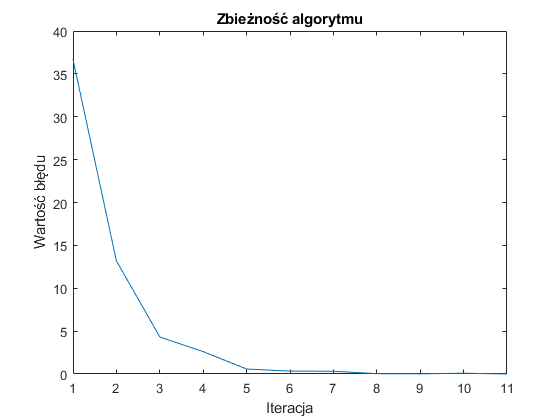

plot(diff(1:end,1),diff(1:end,2))
title('Zbieżność algorytmu')
xlabel('Iteracja')
ylabel('Wartość błędu')